# Homework 3: 

# Inversion of the Integral kernel $\mathrm{d}(y)=\int_0^1xe^{-xy}\mathrm{m}(x)\mathrm{d}x$

## 3 May 2026 by Ji,Haozheng

## (a) Discretization of the integral equation

We discretize the integral equation using a grid with $N-1$ points over the interval $[0,1]$ $x=0$ gives no contribution, Let $\mathrm{d}(y_j)=\sum_{i=1}^{N-1}x_ie^{-x_iy_j}\mathrm{m}(x_i)\Delta x $, then $\mathrm{G_{ij}}=x_ie^{-x_iy_j}\Delta x$.

clc; clear; close all; 
y=(0.025:0.05:0.975)';
d=[0.2388,0.2319,0.2252,0.2188,0.2126,0.2066,0.2008,0.1952,0.1898,0.1846,...
    0.1795,0.1746,0.1699,0.1654,0.1610,0.1567,0.1526,0.1486,0.1447,0.1410]';
dim=length(d);

N=21;
x=linspace(0,1,N);
dx=x(2)-x(1);
x=x(2:end);
G=zeros(dim,N-1);
for ii = 1:dim
    for jj = 1:N-1
        G(ii,jj)=x(jj)*exp(-x(jj)*y(ii))*dx;
    end
end

We can obtain the least-squares solution as $\mathbf{m= ({G}^T {G})^{-1} {G}^T {d}}$ iff $\text{dim(Data)\ge N-1$.

m_lst=(G'*G)\(G'*d);

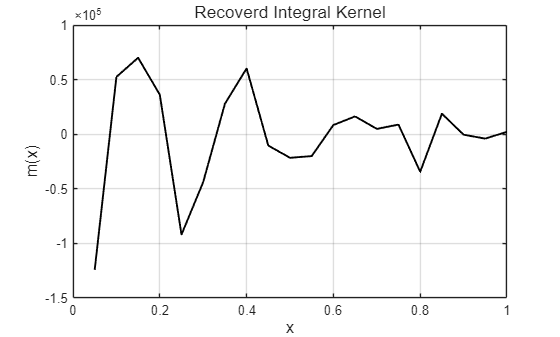

figure;
plot(x, m_lst, 'k-', 'LineWidth', 1.4);
xlabel('x','FontSize',12);
ylabel('m(x)','FontSize',12);
title('Recoverd Integral Kernel','FontSize',13);
grid on; box on;

### (b) Calculate the singular values and the condition number of $\mathrm{G}$

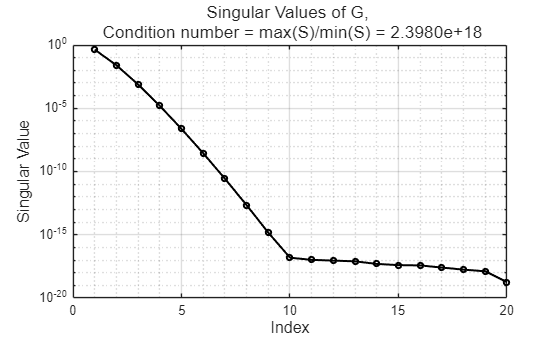

S=svd(G); 
C=cond(G);
figure;
plot((1:length(S)),S, 'k-o', 'LineWidth', 1.5, 'MarkerSize',4);
set(gca,'YScale','log')
xlabel('Index','FontSize', 12);
ylabel('Singular Value','FontSize', 12);
title(sprintf('Singular Values of G, \n Condition number = max(S)/min(S) = %.4e', C), 'FontSize', 13);
grid on; grid minor; box on;

### (c) Use zeroth-order Tikhonov regularization to solve the problem with SVD-form solution

To stabilize the ill-conditioned system, we apply zeroth-order Tikhonov Regularization $\text{min}\,||\mathrm{m}||_2^2$.

$\min_{\mathrm{m}} |\mathrm{Gm - d|^2 + \alpha^2 |m}|^2,$ where $\alpha$  is the regularization parameter. $\mathrm{Gm=d}$ can be rewritten as $\mathrm{(G^\top G+\alpha^2 I)m=G^\top d}$.

Using the singular value decomposition ($$\mathrm{G = U SV^\top}$$), the solution can be expressed as$\mathrm{m=V(S^\top S+\alpha^2 I)^{-1}(S^\top U^\top d)}$. $\mathrm{(S^\top S+\alpha^2 I)^{-1}S^\top}$ can be easily handled using filter factor which avoids matrix inversion.

If we use the least-square method and choose a small $\alpha$, $\mathrm{m=(G^\top G+\alpha^2 I)^{-1}G^\top d}$ will lead to numerical instability and software warnings, as the following results show.

We compute the solution using both formulations and observe that they are equivalent. 

[U, Sigma, V]=svd(G);
I=eye(size(Sigma,2),size(Sigma,2));
alpha=1e-9;
m_ls=V*inv(Sigma'*Sigma+alpha^2*I)*Sigma'*U'*d;

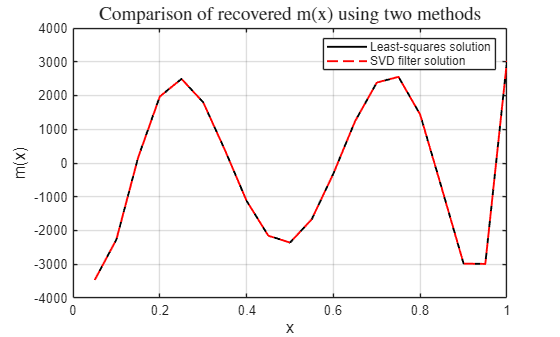

filter=1./(diag(Sigma'*Sigma)+alpha^2);
m_filter=V*(filter.*Sigma'*U'*d); 
figure; hold on; grid on; box on;
plot(x, m_ls, 'k', 'LineWidth', 1.4);
plot(x,m_filter,'r--', 'LineWidth', 1.4);
xlabel('x','FontSize',12);
ylabel('m(x)','FontSize',12);
legend('Least-squares solution','SVD filter solution');
title(sprintf('Comparison of recovered m(x) using two methods'),'FontSize',14, 'Interpreter','latex');

### Different regularization parameters lead to different $\mathrm{m}(x)$ shapes.

The results for different values of  $\alpha$ show that small $\alpha$ leads to unstable and oscillatory solutions, while larger $\alpha$ produces smoother solutions.

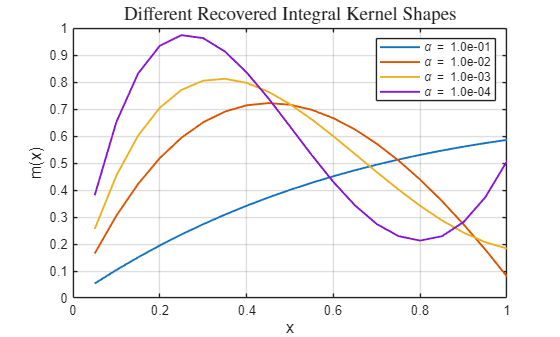

alpha_space=logspace(-1,-4,4);
figure;
hold on;
for ii = 1:length(alpha_space)
    alpha=alpha_space(ii);
    filter=1./(diag(Sigma'*Sigma)+alpha^2);
    m=V*(filter.*Sigma'*U'*d); 
    plot(x, m, 'LineWidth', 1.4);
end
xlabel('x','FontSize',12);
ylabel('m(x)','FontSize',12);
title(sprintf('Different Recovered Integral Kernel Shapes'),'FontSize',14, 'Interpreter','latex');
legend(cellstr(num2str(alpha_space','\\alpha = %.1e')), ...
       'Location','northeast','FontSize',9);
grid on; box on

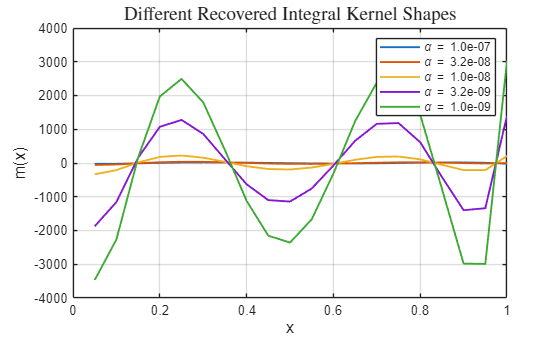

alpha_space=logspace(-7,-9,5);
figure;
hold on;
for ii = 1:length(alpha_space)
    alpha=alpha_space(ii);
    filter=1./(diag(Sigma'*Sigma)+alpha^2);
    m=V*(filter.*Sigma'*U'*d); 
    plot(x, m, 'LineWidth', 1.4);
end
xlabel('x','FontSize',12);
ylabel('m(x)','FontSize',12);
title(sprintf('Different Recovered Integral Kernel Shapes'),'FontSize',14, 'Interpreter','latex');
legend(cellstr(num2str(alpha_space','\\alpha = %.1e')), ...
       'Location','northeast','FontSize',9);
grid on; box on

### (d) Use L-curve criterion to pick the regularization parameter $\alpha$

From the following computational time comparison, we can see the SVD-based filter factor method have higher numerical efficiency.

The optimal regularization parameter is chosen by locating the corner of the L-curve. 

We use the numerical curvature $\kappa=\frac{|x'(t)y''(t)-y'(t)x''(t)|}{(x' (t)^2+y'(t)^2)^{3/2}}$ to chose the best hyper-parameters (largest curvature)

figure;
hold on;
alpha_space=logspace(-8,-3.8,500);
[Residual_norm,Model_norm,time]=compute_Lcurve(alpha_space,G,d,U,Sigma,V,0);
plot(Residual_norm,Model_norm, 'k', 'LineWidth', 1.4);
fprintf('Using filter factor solve Regularization Equation, costing %.4f seconds\n', time);

Using filter factor solve Regularization Equation, costing 0.0213 seconds


[Residual_norm,Model_norm,time]=compute_Lcurve(alpha_space,G,d,U,Sigma,V,1);
plot(Residual_norm,Model_norm, 'r--', 'LineWidth', 1.4);
fprintf('Using least square method solve Regularization Equation, costing %.4f seconds\n', time);

Using least square method solve Regularization Equation, costing 0.0080 seconds


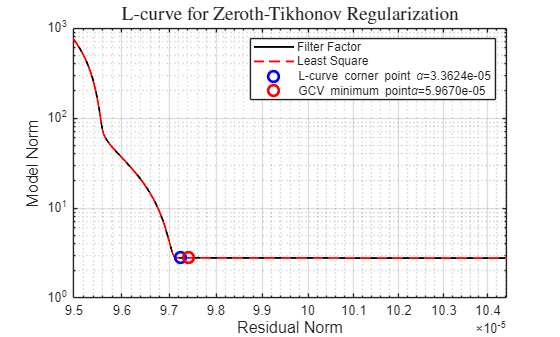

d1R = diff(log(Residual_norm));
d1M = diff(log(Model_norm));
d2R = diff(log(Residual_norm),2);
d2M = diff(log(Model_norm),2);
kappa = abs(d2R .* d1M(1:end-1) - d1R(1:end-1) .* d2M) ...
      ./ (d1R(1:end-1).^2 + d1M(1:end-1).^2).^(3/2);

[~, idx] = max(kappa);
alpha_lc = alpha_space(idx+1);
[R,M]=compute_Lcurve(alpha_lc,G,d,U,Sigma,V,1);
plot(R, M, 'bo', 'MarkerSize', 8, 'LineWidth', 2);
gcv=5.967021130238468e-05;
[R,M]=compute_Lcurve(gcv,G,d,U,Sigma,V,1);
plot(R, M, 'ro', 'MarkerSize', 8, 'LineWidth', 2);
xlabel('Residual Norm','FontSize',12);
ylabel('Model Norm','FontSize',12);
set(gca,'XScale','log');
set(gca,'YScale','log');
legend('Filter Factor','Least Square',sprintf('L-curve corner point \\alpha=%.4e',alpha_lc),sprintf('GCV minimum point\\alpha=%.4e',gcv));
title(sprintf('L-curve for Zeroth-Tikhonov Regularization'),'FontSize',14, 'Interpreter','latex');
grid on; box on;

The following code provides a more local view around the corner point $\alpha=3.3624\times 10^{-5}$.

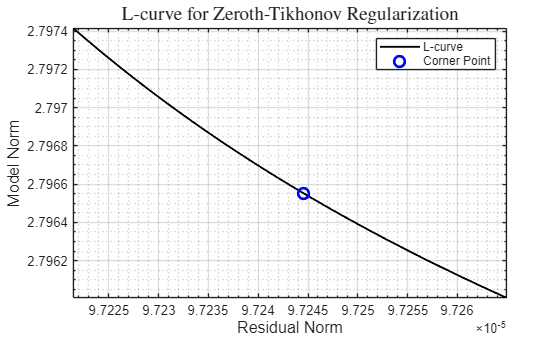

figure;
hold on;
[Residual_norm,Model_norm,time]=compute_Lcurve(linspace(alpha_space(idx+1-10),alpha_space(idx+1+7),100),G,d,U,Sigma,V,0);
plot(Residual_norm,Model_norm, 'k', 'LineWidth', 1.4);
[R,M]=compute_Lcurve(alpha_space(idx+1),G,d,U,Sigma,V,1);
plot(R, M, 'bo', 'MarkerSize', 8, 'LineWidth', 2);
xlabel('Residual Norm','FontSize',12);
ylabel('Model Norm','FontSize',12);
set(gca,'XScale','log');
set(gca,'YScale','log');
legend('L-curve','Corner Point')
title(sprintf('L-curve for Zeroth-Tikhonov Regularization'),'FontSize',14, 'Interpreter','latex');
grid on; box on;

### (d) Use Generalized Cross Validation to pick the regularization parameter $\alpha$

The generalized inverse of $\mathrm{G}$ is $\mathrm{G}^{-g}= \left( \mathrm{G}^\top \mathrm{G} + \alpha^2 \mathrm{I} \right)^{-1}\mathrm{G^\top}$, $\mathrm{GG^{-g}=US(S^\top S +\alpha^2 I)^{-1}S^\top U^\top}$

and the Generalized Cross Validation (GCV) function is defined as $g(\alpha)=\frac{\text{dim(data)}||\mathrm{Gm}_{\alpha,\mathrm{L}}-\mathrm{d}||_2^2}{(\text{Tr}(\mathrm{I-GG}^{-g}))^2}$

We can simplify the GCV function using $||\mathrm{Gm}_{\alpha,\mathrm{L}}-\mathrm{d}||_2^2=||\text{Residual}||_2^2$  and $\mathrm{\text{Tr}(I-US(S^\top S +\alpha^2 I)^{-1}S^\top U^\top)
=\text{Tr}(I)-\text{Tr}(S(S^\top S +\alpha^2 I)^{-1}S^\top)
=\text{Tr}(I)-\text{Tr}(S^\top S(S^\top S +\alpha^2 I)^{-1})}$.

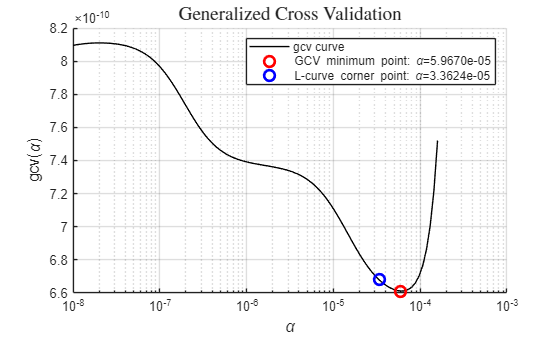

alpha_space=logspace(-8,-3.8,100);
g_alpha=zeros(1,length(alpha_space));
for ii = 1:length(alpha_space)
    alpha=alpha_space(ii);
    filter=1./(diag(Sigma'*Sigma)+alpha^2);
    m=V*(filter.*Sigma'*U'*d);
    Numer=(size(G,1))*norm(G*m-d)^2;
    Denom=sum((1-diag(Sigma'*Sigma).*filter))^2;
    g_alpha(ii)=Numer/Denom;
end


[g_gcv,b]=min(g_alpha);
alpha_gcv=alpha_space(b);
figure;hold on;
plot(alpha_space,g_alpha,'k')
plot(alpha_gcv,g_gcv, 'ro', 'MarkerSize', 8, 'LineWidth', 2);

    filter=1./(diag(Sigma'*Sigma)+alpha_lc^2);
    m=V*(filter.*Sigma'*U'*d);
    Numer=(size(G,1))*norm(G*m-d)^2;
    Denom=sum((1-diag(Sigma'*Sigma).*filter))^2;
    g_lc=Numer/Denom;

plot(alpha_lc,g_lc, 'bo', 'MarkerSize', 8, 'LineWidth', 2);
set(gca,'XScale','log');
xlabel('\alpha','FontSize',12);
ylabel('gcv(\alpha)','FontSize',12);
legend('gcv curve',sprintf('GCV minimum point: \\alpha=%.4e',alpha_gcv),sprintf('L-curve corner point: \\alpha=%.4e',alpha_lc))
title(sprintf('Generalized Cross Validation'),'FontSize',14, 'Interpreter','latex');
grid on;

We plot the recovered intregral kernel and compare the corresponding objective function terms from different methods. It can be seen that the difference betweent the two optima $\alpha$ is small.

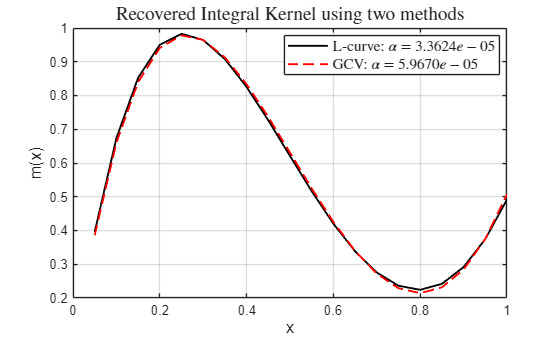

figure;
hold on;
filter = 1./(diag(Sigma'*Sigma) + alpha_lc^2);
m_lc   = V*(filter.*Sigma'*U'*d); 
plot(x, m_lc, 'k', 'LineWidth', 1.4);

filter = 1./(diag(Sigma'*Sigma) + alpha_gcv^2);
m_gcv  = V*(filter.*Sigma'*U'*d); 
plot(x, m_gcv, 'r--', 'LineWidth', 1.4);
xlabel('x', 'FontSize', 12);
ylabel('m(x)', 'FontSize', 12);
legend( ...
    sprintf('L-curve: $\\alpha = %.4e$', alpha_lc), ...
    sprintf('GCV: $\\alpha = %.4e$', alpha_gcv), ...
    'Location', 'best', ...
    'Interpreter', 'latex', ...
    'FontSize', 11 ...
);
title('Recovered Integral Kernel using two methods','FontSize',14, 'Interpreter','latex');
grid on; box on

function [Residual_norm,Model_norm,time]=compute_Lcurve(alpha_space,G,d,U,Sigma,V,method)
    Residual_norm=zeros(length(alpha_space),1);
    Model_norm=zeros(length(alpha_space),1);
    tic;
    if method==0
        for ii=1:length(alpha_space)
            alpha=alpha_space(ii);
            filter=1./(diag(Sigma'*Sigma)+alpha^2);
            m=V*(filter.*Sigma'*U'*d);
            Residual_norm(ii)=norm(G*m-d);
            Model_norm(ii)=norm(m);
        end
    else 
        I=eye(size(Sigma,2),size(Sigma,2));
        for ii=1:length(alpha_space)
            alpha=alpha_space(ii);
            m=V*inv(Sigma'*Sigma+alpha^2*I)*Sigma'*U'*d;
            Residual_norm(ii)=norm(G*m-d);
            Model_norm(ii)=norm(m);
        end
    end  
    time=toc;
end
        